syms p a02 T2 k1 k2 u f

A = [0 1; 0 -a02/T2];
B = [0;1];
Bf = [0;1/k2];
C = [k1*k2/T2 0];

C*inv(p*eye(2)-A)*(B*u - Bf*f)

$$ans = \frac{k_{1}\,k_{2}\,\left(u-\frac{f}{k_{2}}\right)}{p\,\left(a_{02}+T_{2}\,p\right)}$$

k1 = 1;
a02 = 1;
k2 = 0.5;
T2 = 0.95;
T = 0.5;

A = [0 1; 0 -a02/T2];
B = [0;1];
Bf = [0;1/k2];
C = [k1*k2/T2 0];

Ad = zeros([2 2]);
Bd = zeros([2 1]);
Bdf = zeros([2 1]); 
for i = 0:5
    Ad = Ad + A^i*T^i/factorial(i);
    Bd = Bd + A^i*T^(i+1)/factorial(i+1)*B;
    Bdf = Bdf + A^i*T^(i+1)/factorial(i+1)*Bf;
end

Gg = [0 1; -1 2];
Hg = [1 0];

Tmdl = 50;
xi_initial = [0;0];

warning off
SimNew = sim("target_signal.slx",'ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.g(:,1);
g = SimNew.g(:,2);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,g,'LineWidth',1)
hold on
grid on
xlabel('\it t\rm,\it s')
ylabel('\it g\rm(\itt\rm)')
legend('входное воздействие','Location','best')

xi_initial = [4;4];

warning off
SimNew = sim("target_signal.slx",'ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.g(:,1);
g = SimNew.g(:,2);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,g,'LineWidth',1)
hold on
grid on
xlabel('\it t\rm,\it s')
ylabel('\it g\rm(\itt\rm)')
legend('входное воздействие','Location','best')

rank(ctrb(Ad, Bd))

ans = 2

syms mg3 mg4
syms lg1 lg2
Mg = [1/(k1*k2/T2) 0; mg3 mg4];
Lg = [lg1 lg2];

eqn = Bd*Lg == Mg*Gg - Ad*Mg;

S = solve(eqn);

Mg = [1/(k1*k2/T2) 0; double(S.mg3) double(S.mg4)];
Lg = [double(S.lg1) double(S.lg2)];

Gd = [0 1; 0 0];
Hd = [1 0];

M = sylvester(-Ad, Gd, Bd*Hd);
Koc = Hd*inv(M);

eig(Ad+Bd*Koc)

ans = 1.0e-08 *

   -0.5759
    0.5759


Tmdl = 2.5;
xi_initial = [4;4];

warning off
SimNew = sim("cl_system_1.slx",'ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.out.time;
y = SimNew.out.signals(1).values;
g = SimNew.out.signals(3).values;
e = SimNew.out.signals(2).values;

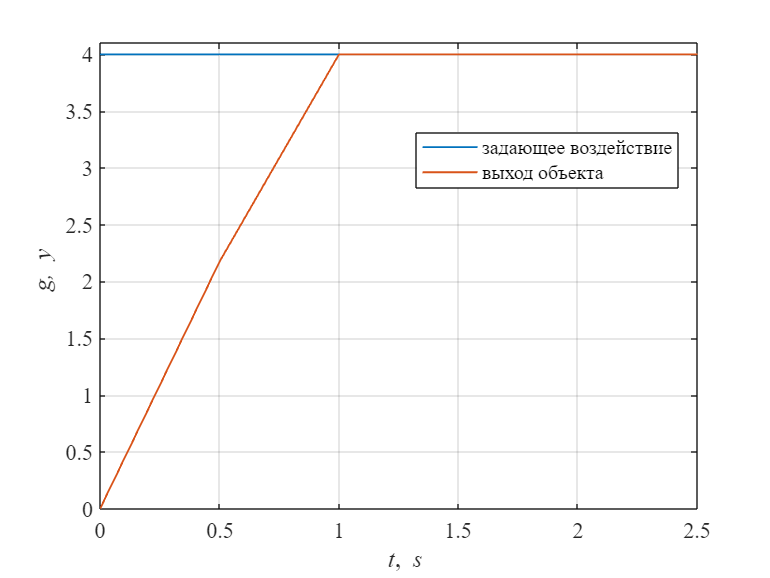

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,g,'LineWidth',1)
hold on
grid on
plot(t,y,'LineWidth',1)
ylim([0 4.1])
xlabel('\it t\rm,\it s')
ylabel('\it g, y')
legend('задающее воздействие','выход объекта','Location','best')

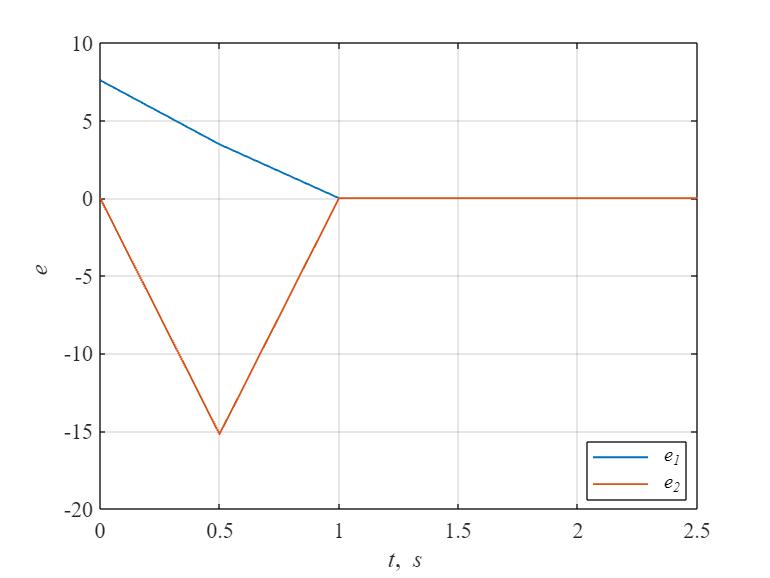

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,e(:,1),'LineWidth',1)
hold on
grid on
plot(t,e(:,2),'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it e')
legend('\it e_1','\it e_2','Location','best')

f0 = 1.5;
f1 = 4.5;
Af = 0;
wf = 0;

Gf = [0 1; -1 2];
Hf = [1 0];

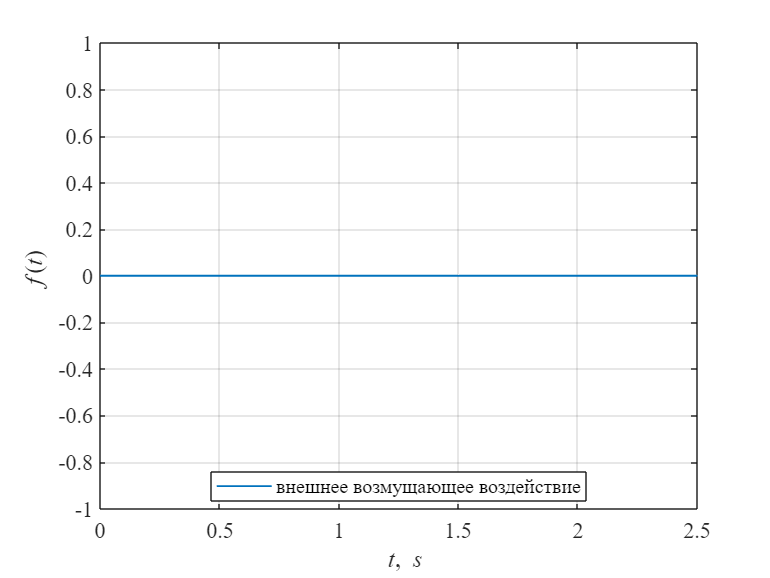

Tmdl = 2.5;
xif_initial = [0;0];

warning off
SimNew = sim("perturb_signal.slx",'ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.f(:,1);
f = SimNew.f(:,2);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,f,'LineWidth',1)
hold on
grid on
xlabel('\it t\rm,\it s')
ylabel('\it f\rm(\itt\rm)')
legend('внешнее возмущающее воздействие','Location','best')

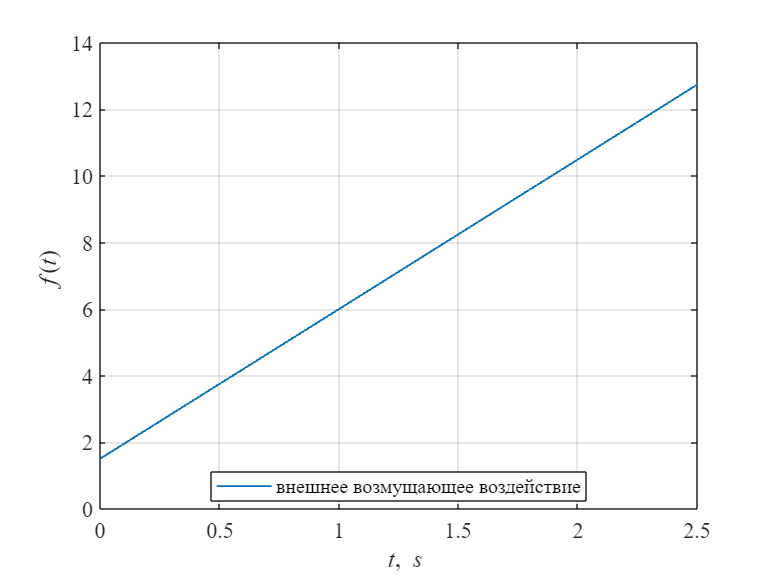

Tmdl = 2.5;
xif_initial = [f0;f0+f1*T];

warning off
SimNew = sim("perturb_signal.slx",'ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.f(:,1);
f = SimNew.f(:,2);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,f,'LineWidth',1)
hold on
grid on
xlabel('\it t\rm,\it s')
ylabel('\it f\rm(\itt\rm)')
legend('внешнее возмущающее воздействие','Location','best')

syms lf1 lf2
Lf = [lf1 lf2];
Bd*Lf

$$ans = \left(\begin{array}{cc} \frac{3807472291839057\,{\mathrm{lf}}_{1}}{36028797018963968} & \frac{3807472291839057\,{\mathrm{lf}}_{2}}{36028797018963968}\\ \frac{3501633234781271\,{\mathrm{lf}}_{1}}{9007199254740992} & \frac{3501633234781271\,{\mathrm{lf}}_{2}}{9007199254740992} \end{array}\right)$$

Bdf*Hf

ans =     0.2114         0
    0.7775         0


solve(Bd*Lf == Bdf*Hf)

ans = struct with fields:
    lf1: 2
    lf2: 0


Lf = [2 0];

Tmdl = 2.5;

xi_initial = [4;4];
xif_initial = [f0;f0+f1*T];

warning off
SimNew = sim("cl_system_1.slx",'ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.out.time;
y = SimNew.out.signals(1).values;
g = SimNew.out.signals(3).values;
e = SimNew.out.signals(2).values;
f = SimNew.out.signals(4).values;

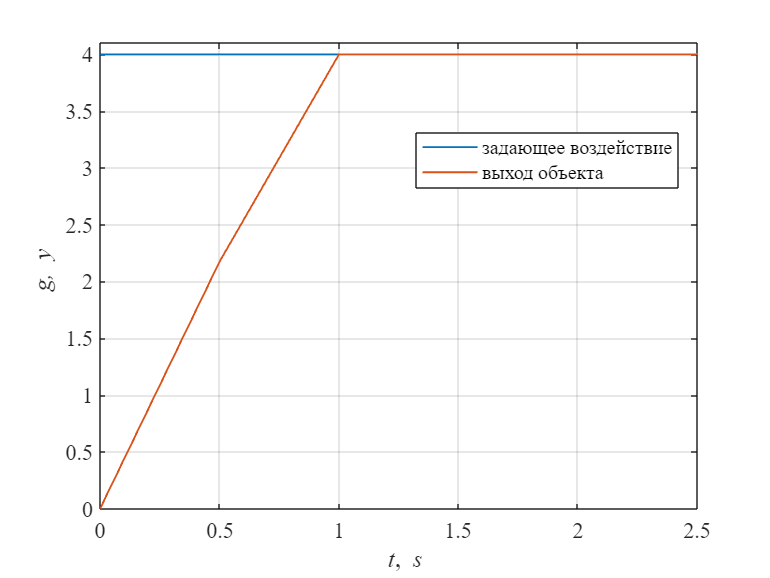

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,g,'LineWidth',1)
hold on
grid on
plot(t,y,'LineWidth',1)
ylim([0 4.1])
xlabel('\it t\rm,\it s')
ylabel('\it g, y')
legend('задающее воздействие','выход объекта','Location','best')

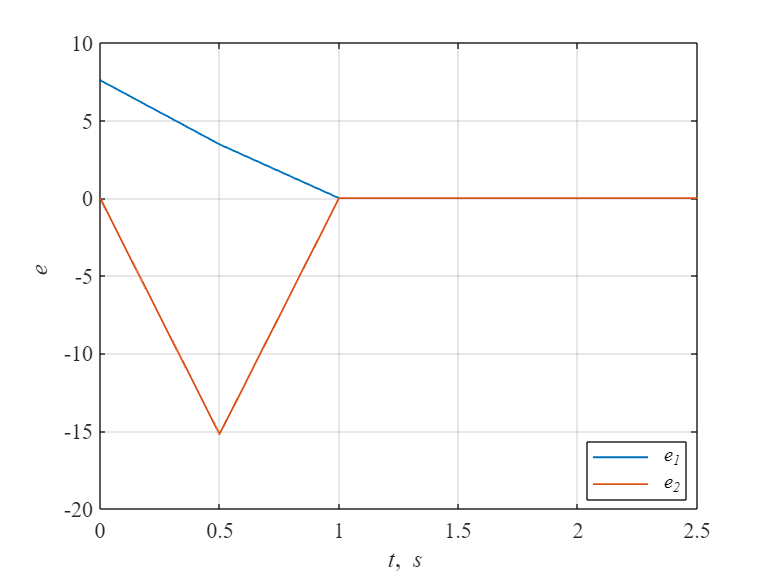

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,e(:,1),'LineWidth',1)
hold on
grid on
plot(t,e(:,2),'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it e')
legend('\it e_1','\it e_2','Location','best')

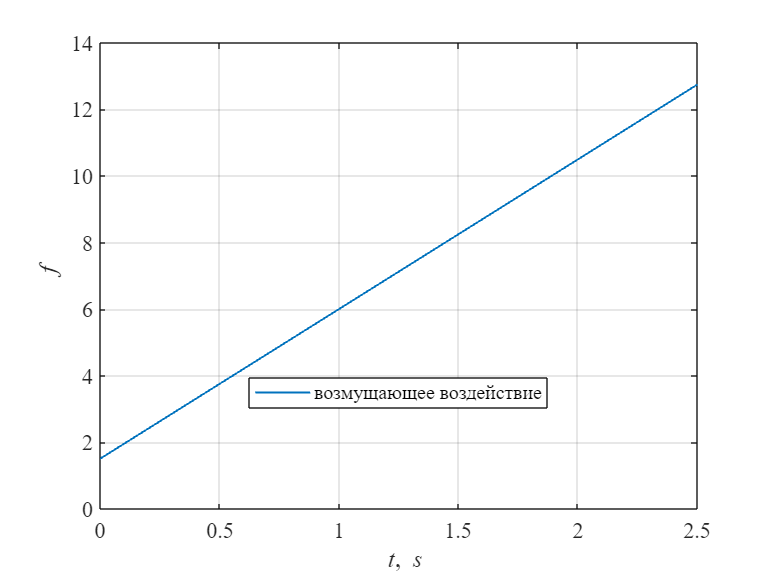

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,f,'LineWidth',1)
hold on
grid on
xlabel('\it t\rm,\it s')
ylabel('\it f')
legend('возмущающее воздействие','Location','best')